clc; clear; close all

wire1_initial_position = [257.59 665.50]; % um
wire2_initial_position = [337.94 672.44];
wire3_initial_position = [465.30 376.40];
wire4_initial_position = [614.38 704.40];

wire1=importdata('wire1sorted.txt');
wire2=importdata('wire2sorted.txt');
wire3=importdata('wire3sorted.txt');
wire4=importdata('wire4sorted.txt');

lens = 20; %20 40
if lens == 10
    pixeltoum = 0.65; %um/pixal
elseif lens == 40
    pixeltoum = 0.1625; %um/pixal
elseif lens == 20
    pixeltoum = 0.3250;
end


wire1_dx = wire1(:,4) - wire1(1,4);
wire1_dy = wire1(:,5) - wire1(1,5);
wire1_dz = wire1(:,3) - wire1(1,3);

wire2_dx = wire2(:,4) - wire2(1,4);
wire2_dy = wire2(:,5) - wire2(1,5);
wire2_dz = wire2(:,3) - wire2(1,3);

wire3_dx = wire3(:,4) - wire3(1,4);
wire3_dy = wire3(:,5) - wire3(1,5);
wire3_dz = wire3(:,3) - wire3(1,3);

wire4_dx = wire4(:,4) - wire4(1,4);
wire4_dy = wire4(:,5) - wire4(1,5);
wire4_dz = wire4(:,3) - wire4(1,3);

wire1_x = wire1_dx * pixeltoum + wire1_initial_position(1);
wire1_y = wire1_dy * pixeltoum + wire1_initial_position(2);
wire1_z = wire1(:,3);

wire2_x = wire2_dx * pixeltoum + wire2_initial_position(1);
wire2_y = wire2_dy * pixeltoum + wire2_initial_position(2);
wire2_z = wire2(:,3);

wire3_x = wire3_dx * pixeltoum + wire3_initial_position(1);
wire3_y = wire3_dy * pixeltoum + wire3_initial_position(2);
wire3_z = wire3(:,3);

wire4_x = wire4_dx * pixeltoum + wire4_initial_position(1);
wire4_y = wire4_dy * pixeltoum + wire4_initial_position(2);
wire4_z = wire4(:,3);

Lx = 400 ;%um
Ly = 400 ;% um
nooc = 4;
noor = 4;

padR = 50;% um
chipX = Lx * nooc;
chipY = Ly * noor;
% plotChip(chipX,chipY,padR,nooc,noor); hold on

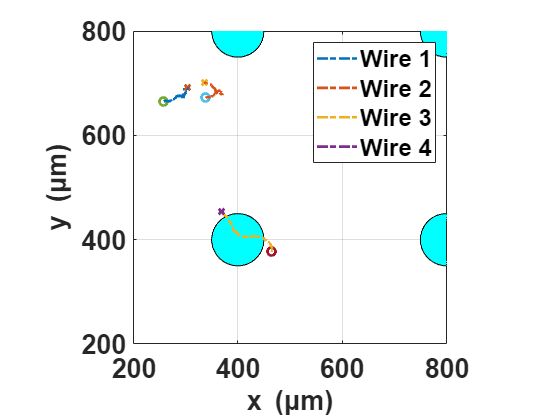

figure(1)
plotChip(chipX,chipY,padR,nooc,noor);
plot3(wire1_x,wire1_y,wire1_z,'-.','LineWidth',2); hold on
plot3(wire2_x,wire2_y,wire2_z,'-.','LineWidth',2); hold on
plot3(wire3_x,wire3_y,wire3_z,'-.','LineWidth',2); hold on
plot3(wire4_x,wire4_y,wire4_z,'-.','LineWidth',2); hold on
plot3(wire1_x(1),wire1_y(1),wire1_z(1),'o','LineWidth',2); hold on
plot3(wire2_x(1),wire2_y(1),wire2_z(1),'o','LineWidth',2); hold on
plot3(wire3_x(1),wire3_y(1),wire3_z(1),'o','LineWidth',2); hold on
plot3(wire4_x(1),wire4_y(1),wire4_z(1),'o','LineWidth',2); hold on
plot3(wire1_x(end),wire1_y(end),wire1_z(end),'x','LineWidth',2); hold on
plot3(wire2_x(end),wire2_y(end),wire2_z(end),'x','LineWidth',2); hold on
plot3(wire3_x(end),wire3_y(end),wire3_z(end),'x','LineWidth',2); hold on
plot3(wire4_x(end),wire4_y(end),wire4_z(end),'x','LineWidth',2); hold off
xlim([200 800])
ylim([200 800])
zlim([0 500])
pbaspect([2 2 1])
ax = gca; 
ax.FontSize = 20; 
ax.FontWeight = 'bold';
grid on;
legend('','','','','','','','','','','','','','','','','Wire 1','Wire 2','Wire 3','Wire 4')
xlabel('x (\mum)','FontSize',20,'FontWeight','bold'); 
ylabel('y (\mum)','FontSize',20,'FontWeight','bold'); 
zlabel('z (\mum)','FontSize',20,'FontWeight','bold')